# SEE data-driven NCC

Read all .txt files in the folder

dinfo = dir('*.txt');
names_cell = {dinfo.name}';
names_Str = convertCharsToStrings(names_cell)

names_Str = 4×1 string array
    "1a_AuNpsNIE.txt"
    "1b_AuNpsBlank.txt"
    "2a_CatalaseNIE.txt"
    "2b_CatalaseBlank.txt"


## Import data by input the files' name

Sig1 = SignalAnalysis(names_Str(1));
Sig2 = SignalAnalysis(names_Str(3));
Back1 = SignalAnalysis(names_Str(2));
Back2 = SignalAnalysis(names_Str(4));

## Preprocess

Sig1.Preprocess("Original units e.g.pA","Time shift e.g. y","Resample e.g. y","Plot resample e.g. y");

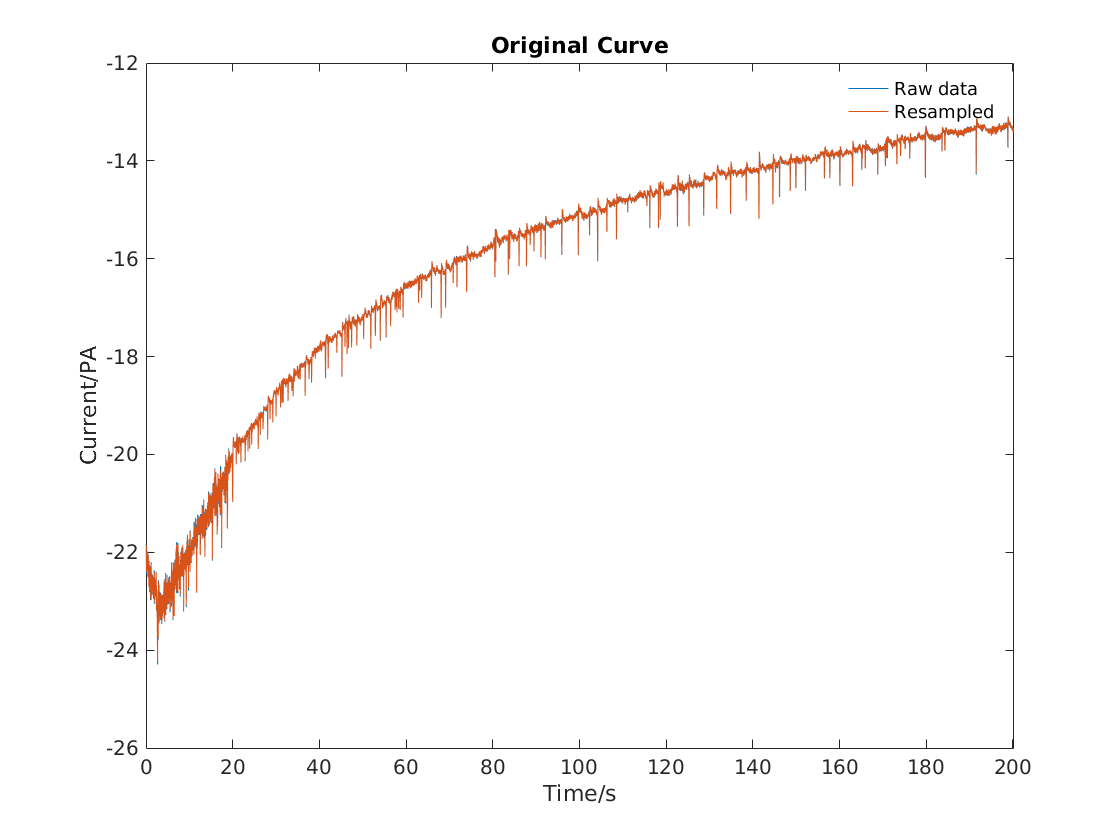

Sig1 = Sig1.Preprocess("A","Y","N","N");
Back1 = Back1.Preprocess("A","Y","N","N");
Sig2 = Sig2.Preprocess("PA","N","Y","Y");

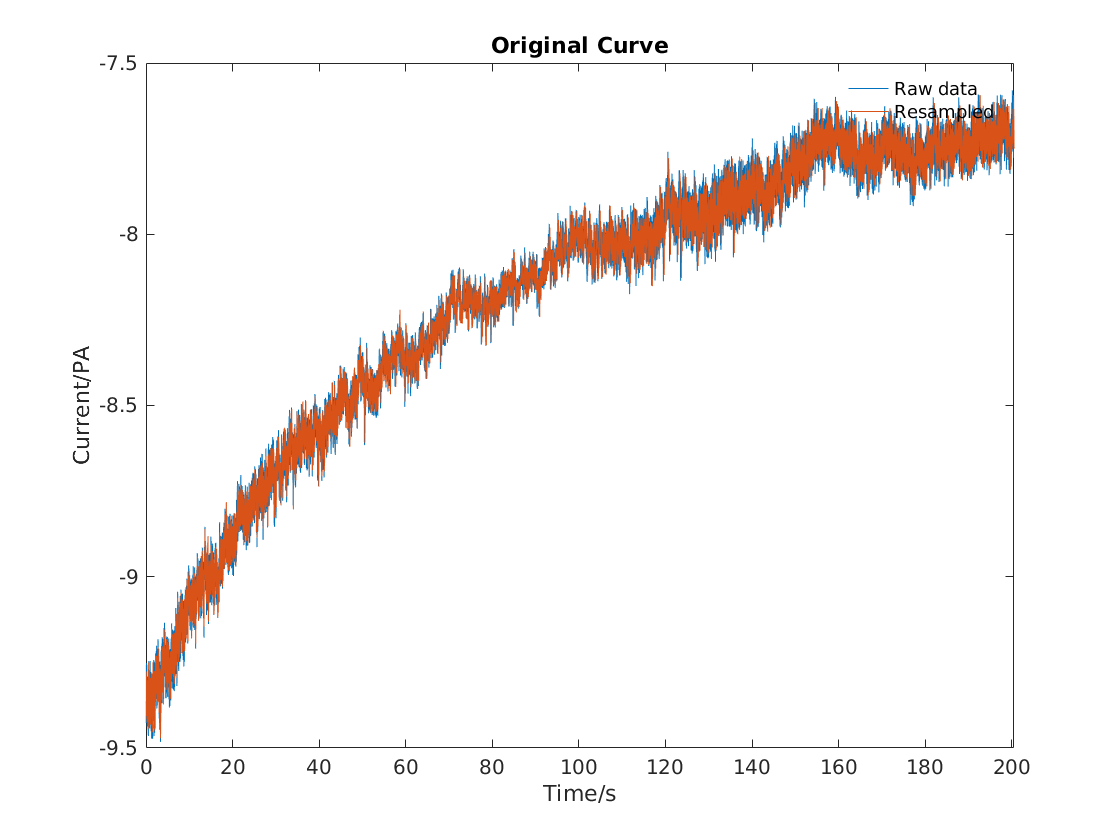

Back2 = Back2.Preprocess("PA","N","Y","Y");

## Denoise

Denoise can either leave frequency it will output the stft plot and set frequency by inputing in the command window

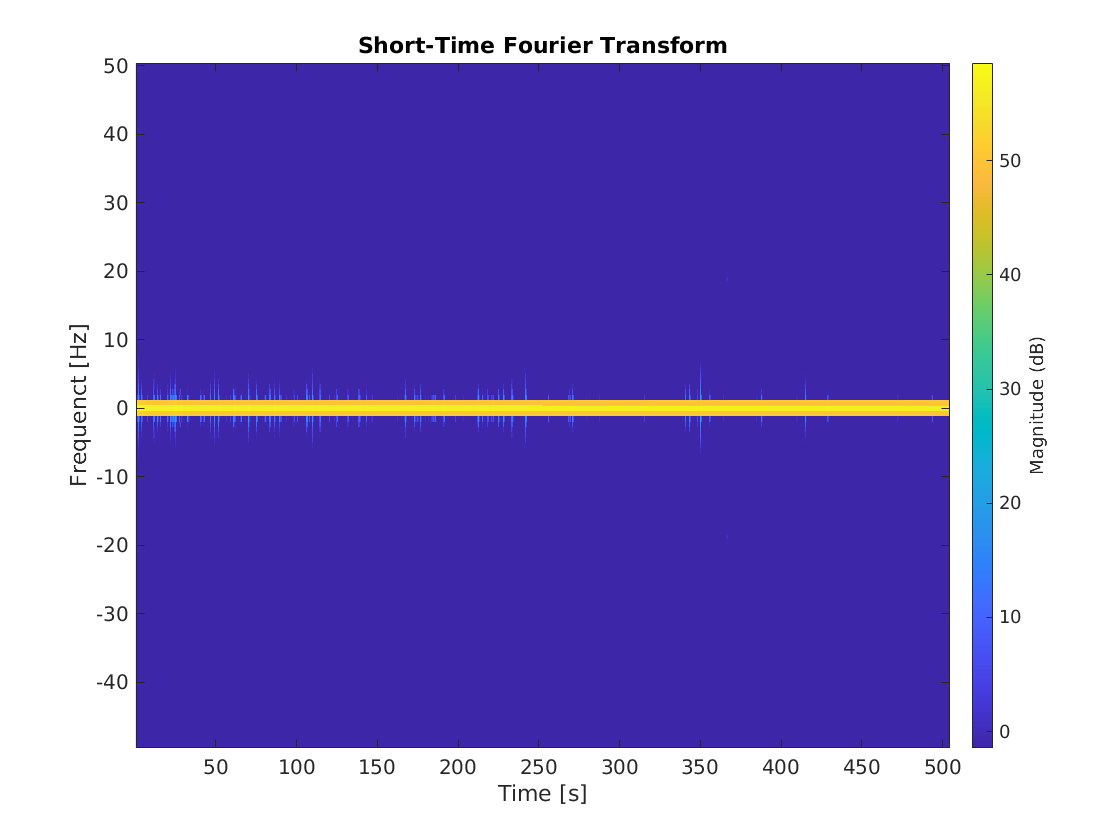

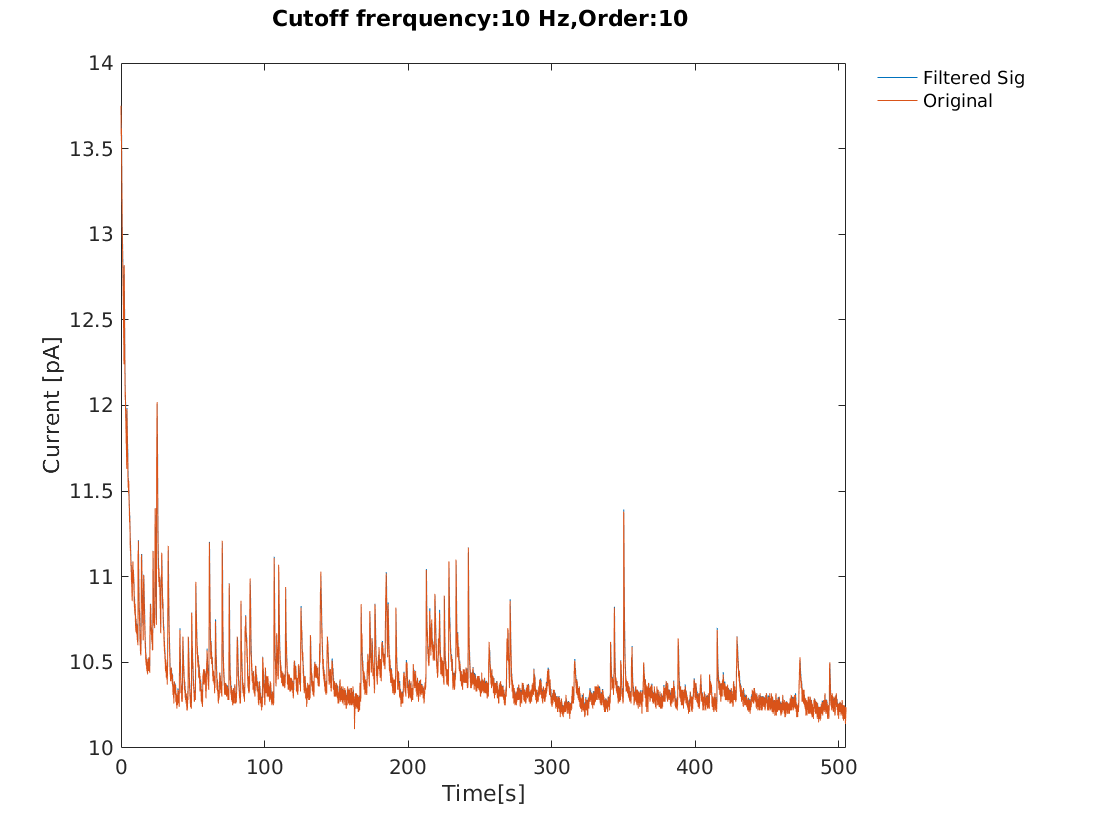

Sig1 = Sig1.Denoise([],10);

Or difectly input the cut-off frequency

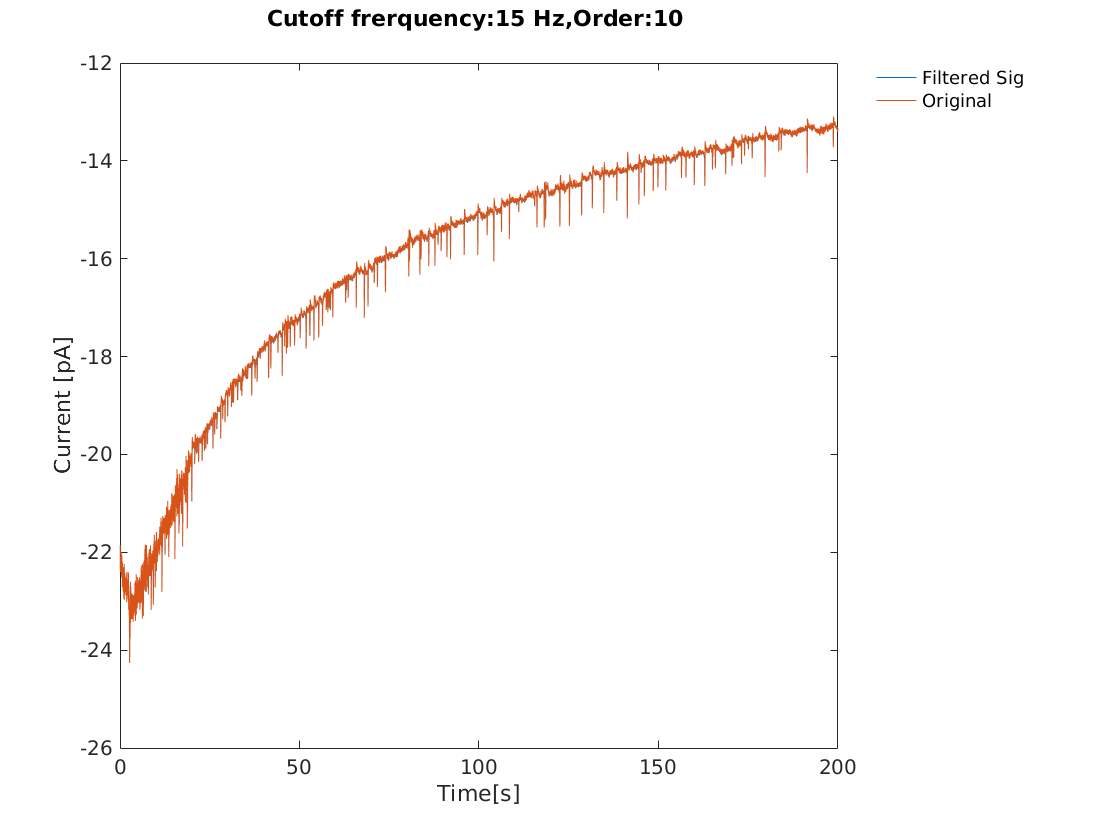

Sig2 = Sig2.Denoise(15,10);

## BackgroundSubtraction Sig1

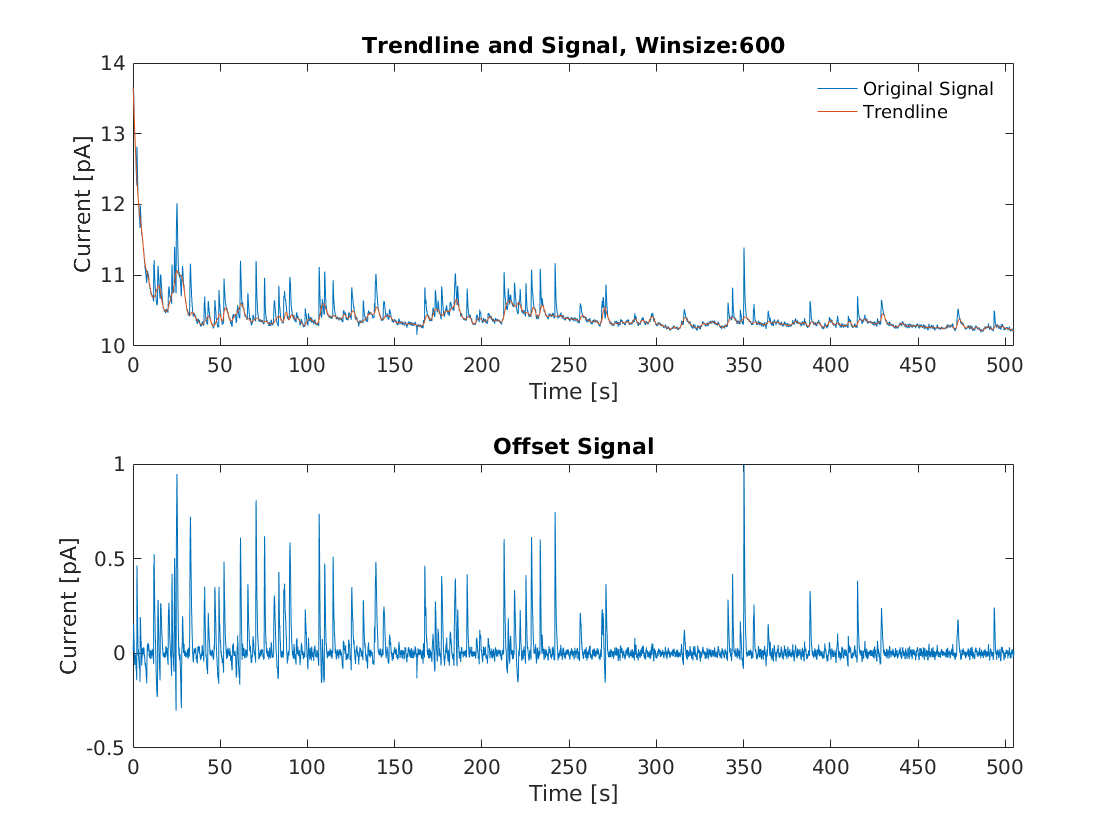

Winsize = 600;
Sig1 = Sig1.BgSub(Winsize,'y');

Back1 = Back1.BgSub(1000,'N');

## BackGroundsub Sig2

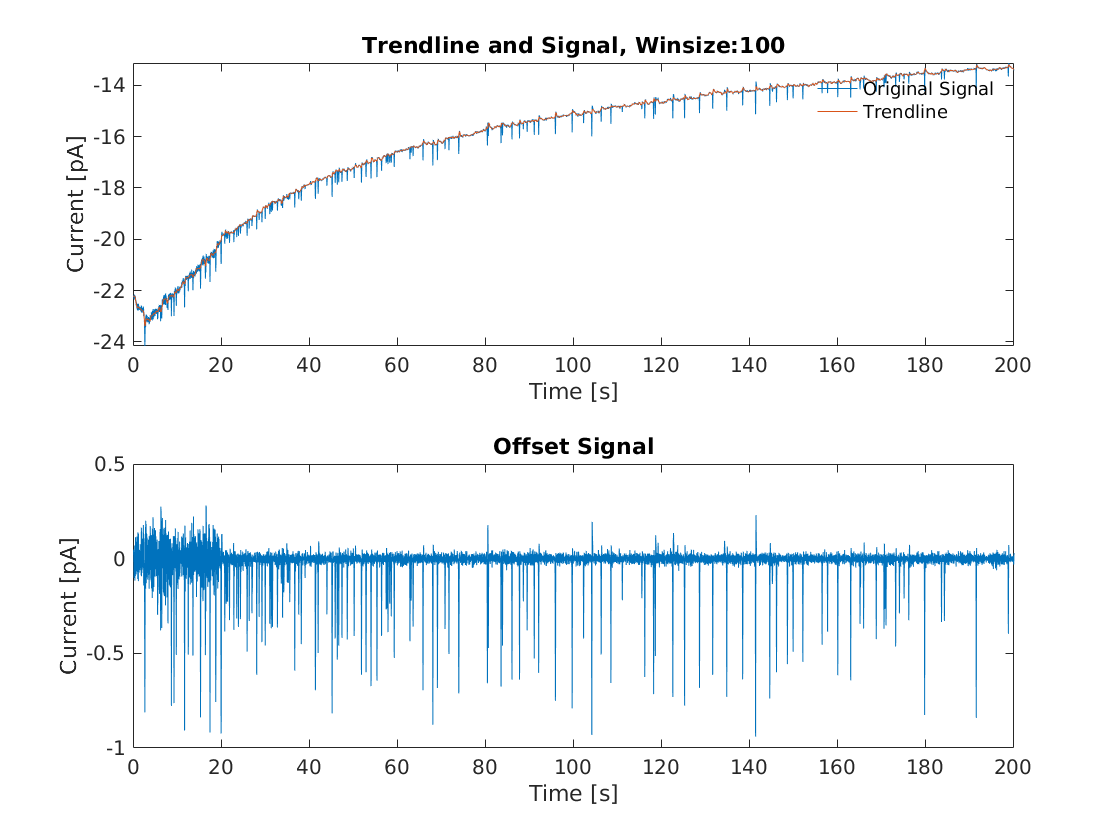

Winsize = 100;
Sig2 = Sig2.BgSub(Winsize,'y');

Back2 = Back2.BgSub(1000,'N');

## flip find peaks

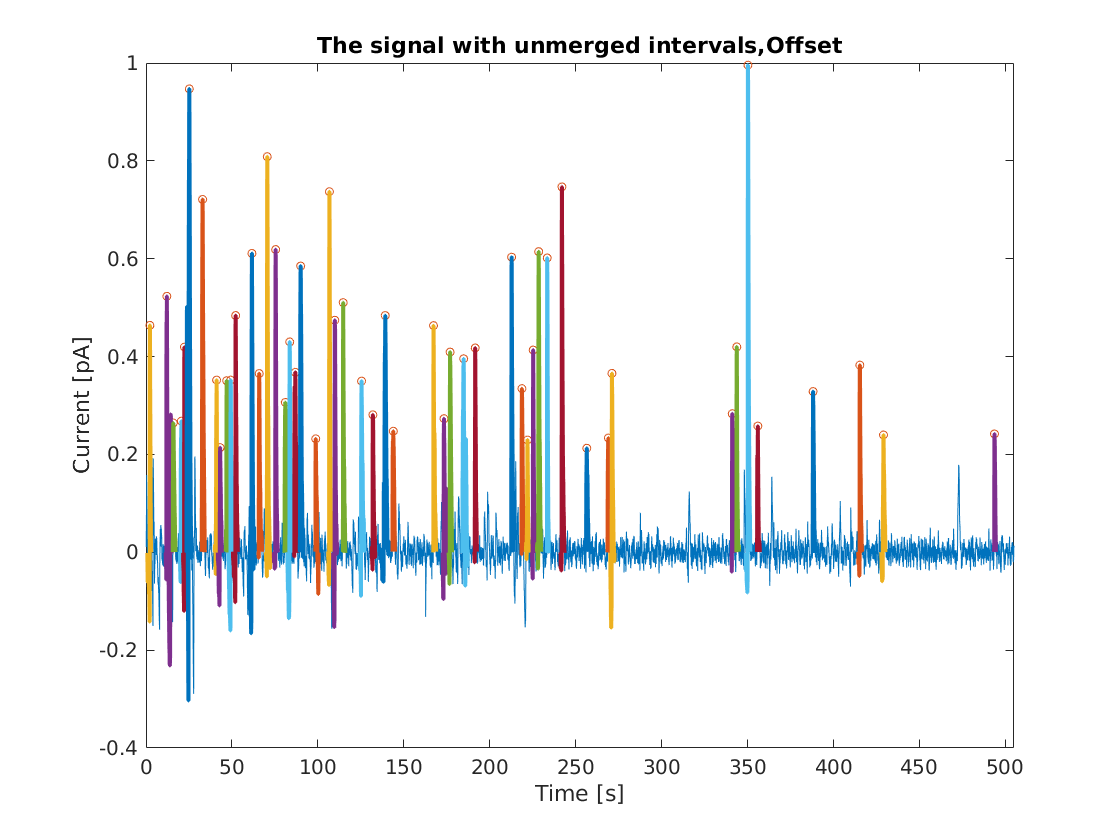

Sig1 = Sig1.FlipFindPeak(Back1.Test_signal_offset,'Oxi','Y',"Offset");

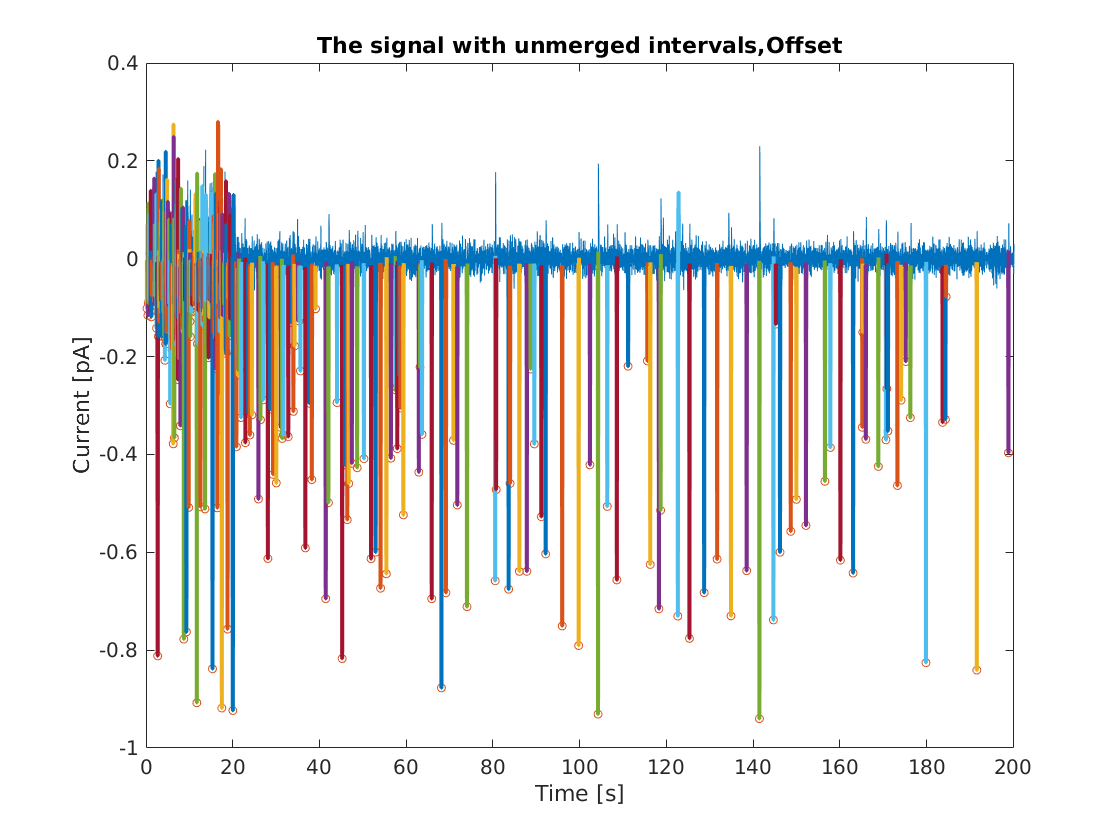

Sig2 = Sig2.FlipFindPeak(Back2.Test_signal_offset,'Red','Y',"Offset");

## TraningSet generation

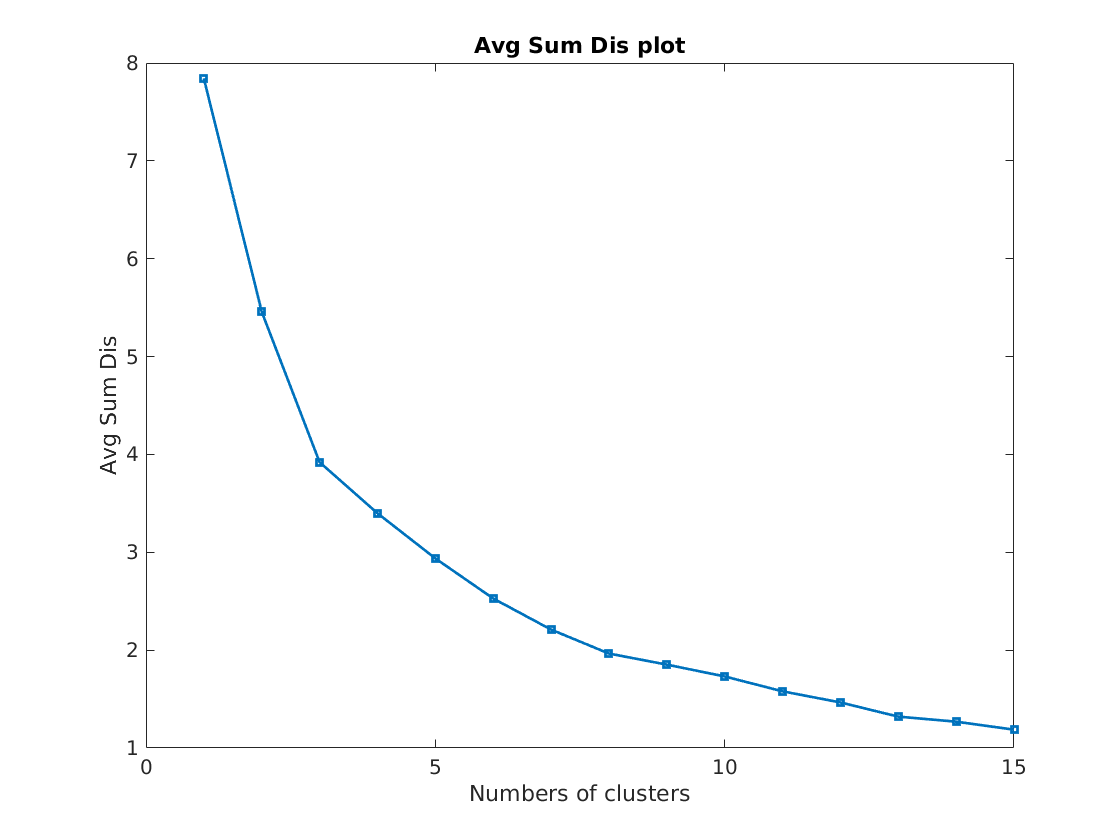

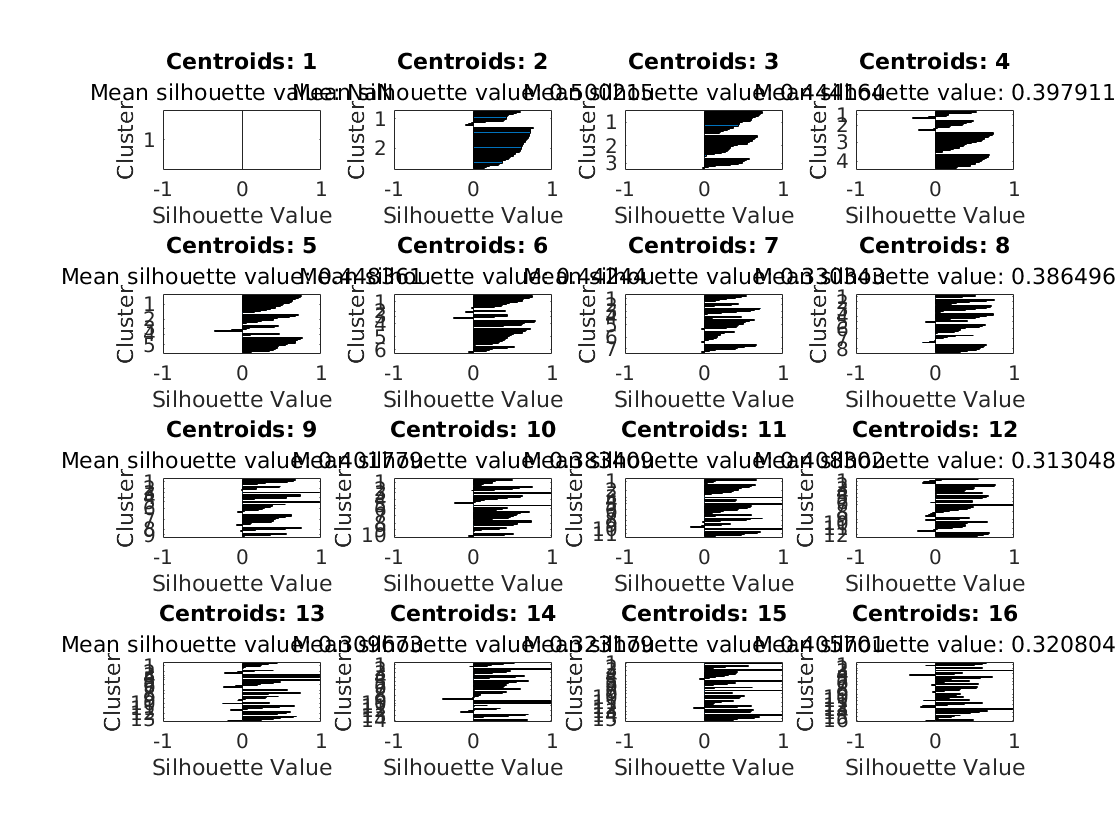

Sig1 = Sig1.GeRawTrainSet('Y','Y');

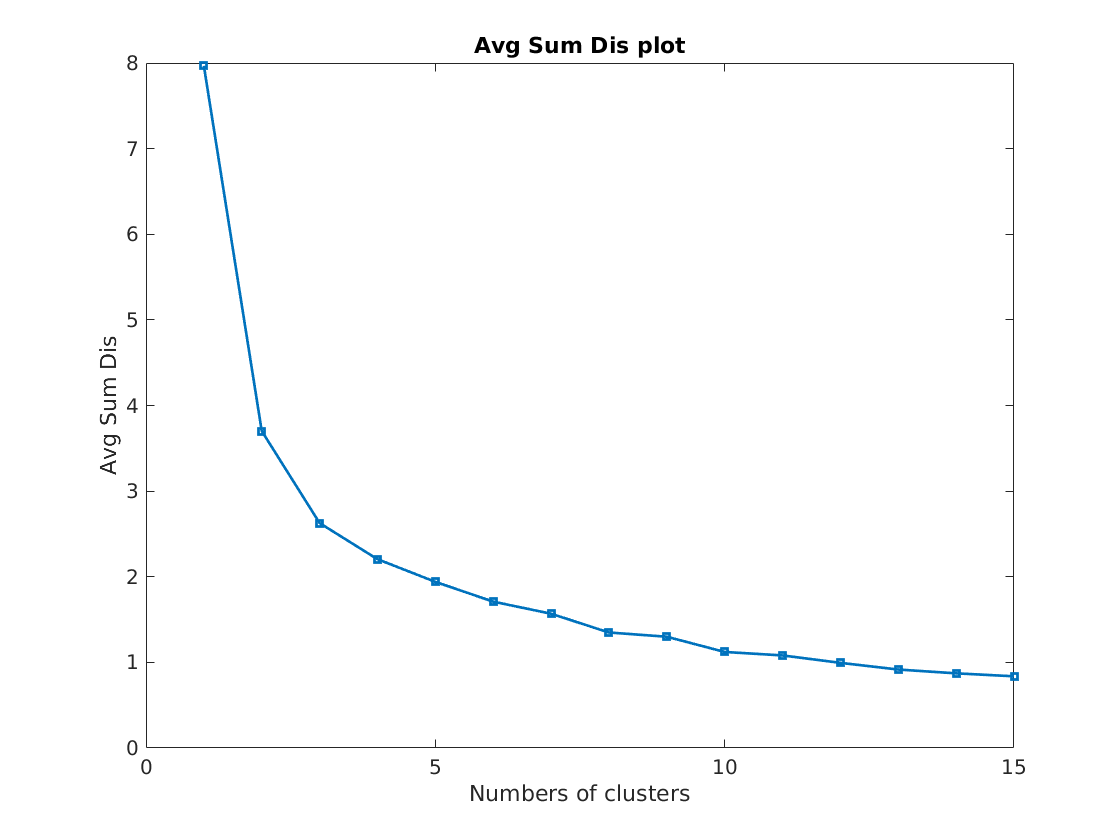

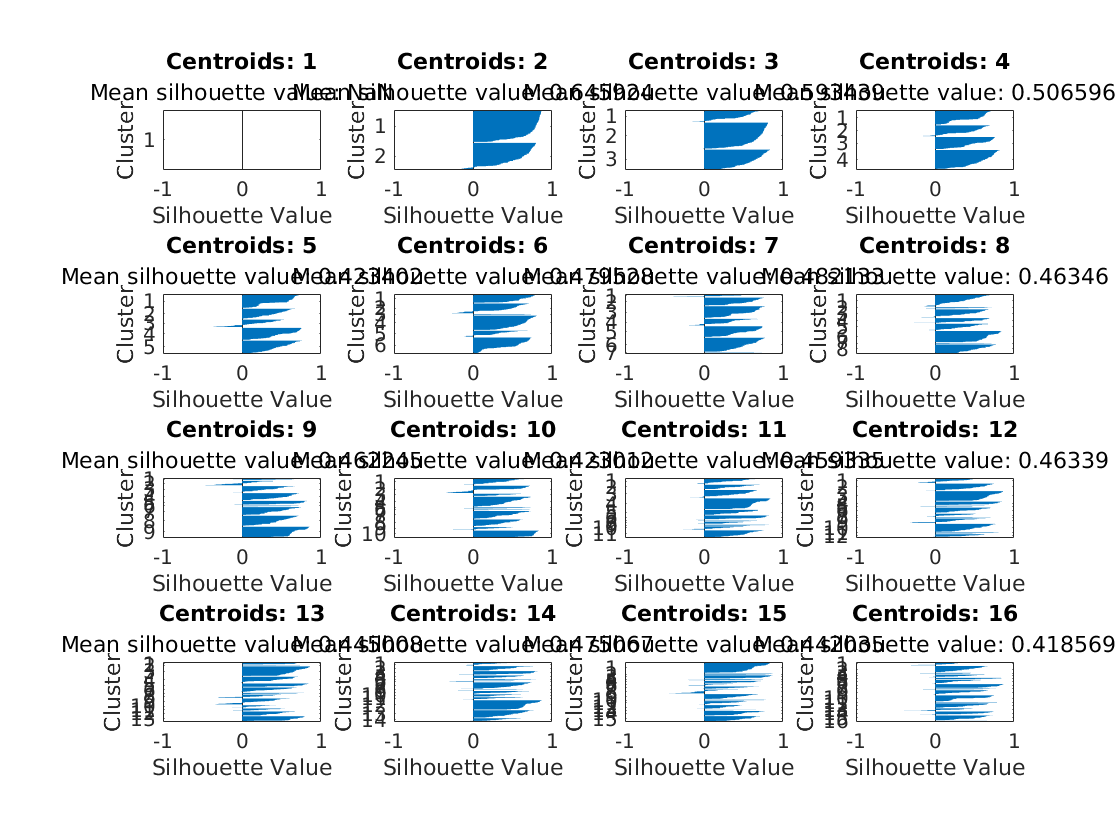

Sig2 = Sig2.GeRawTrainSet('Y','Y');

## Clustering and Raw unregularated templates generation

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


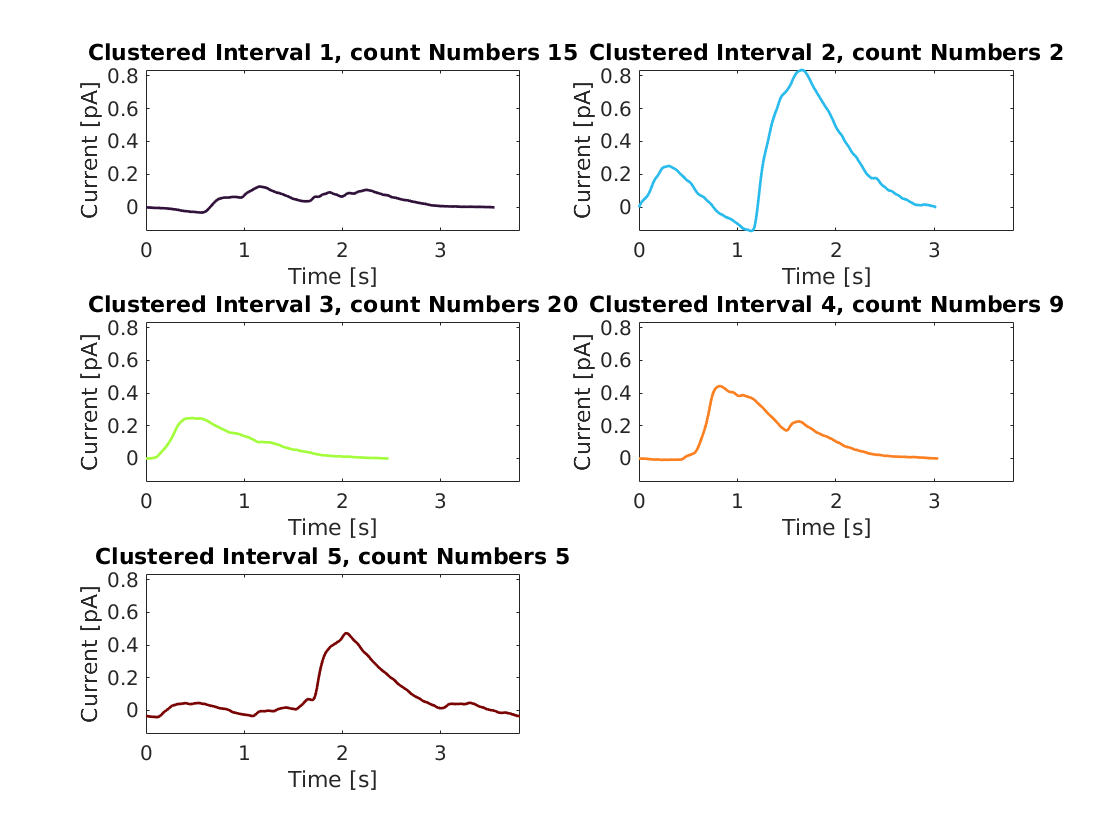

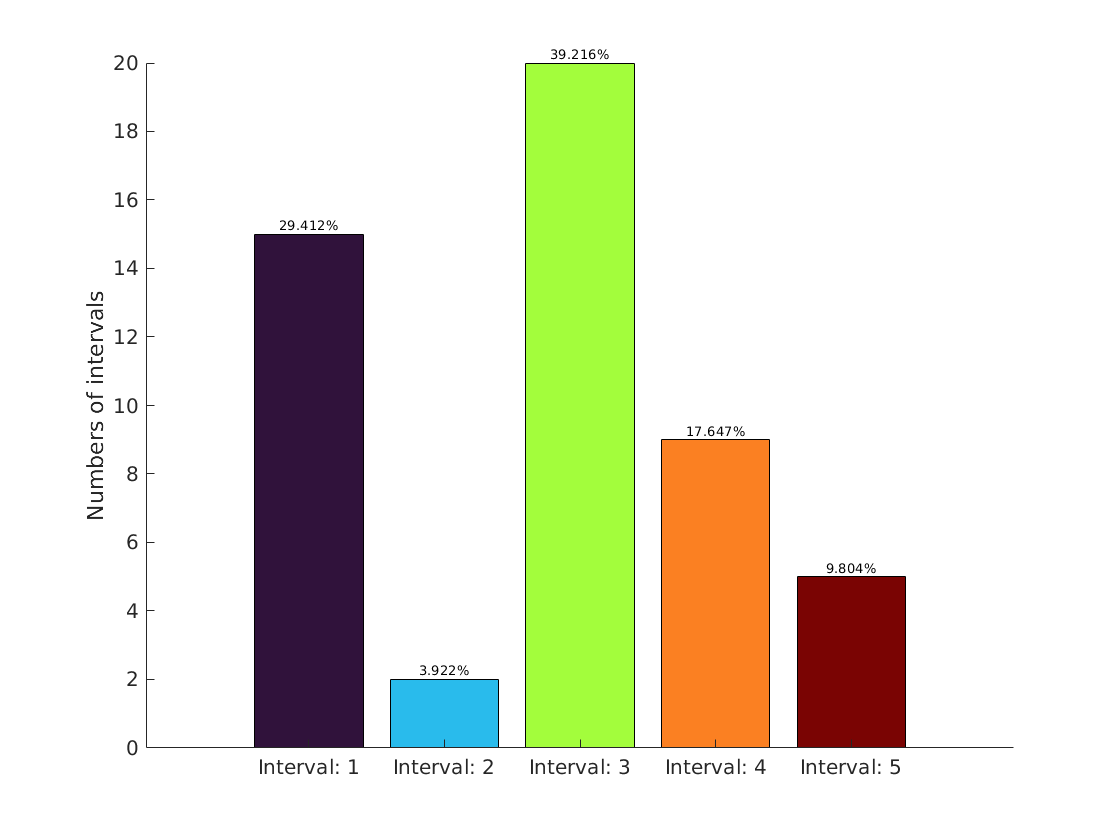

Sig1 = Sig1.KmeansGeRawSigTem(5,'Y',"Y");

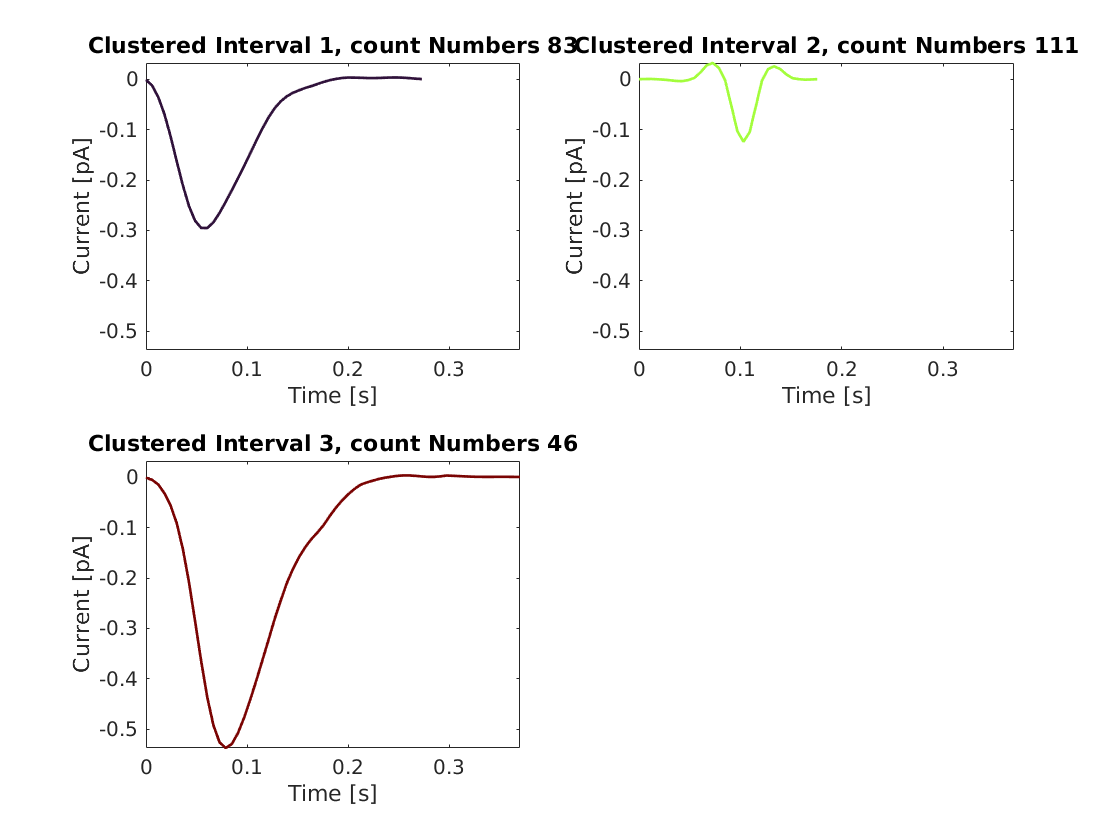

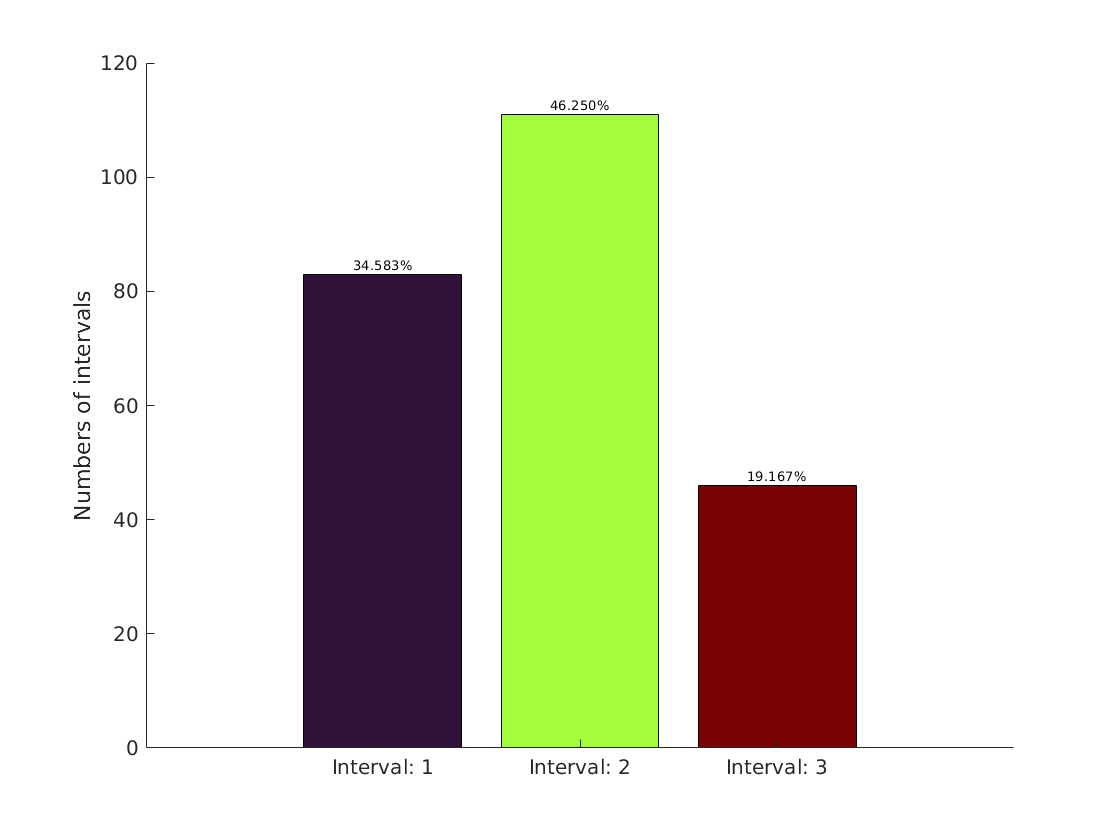

Sig2 = Sig2.KmeansGeRawSigTem(3,'Y',"Y");

## Regulated Templates

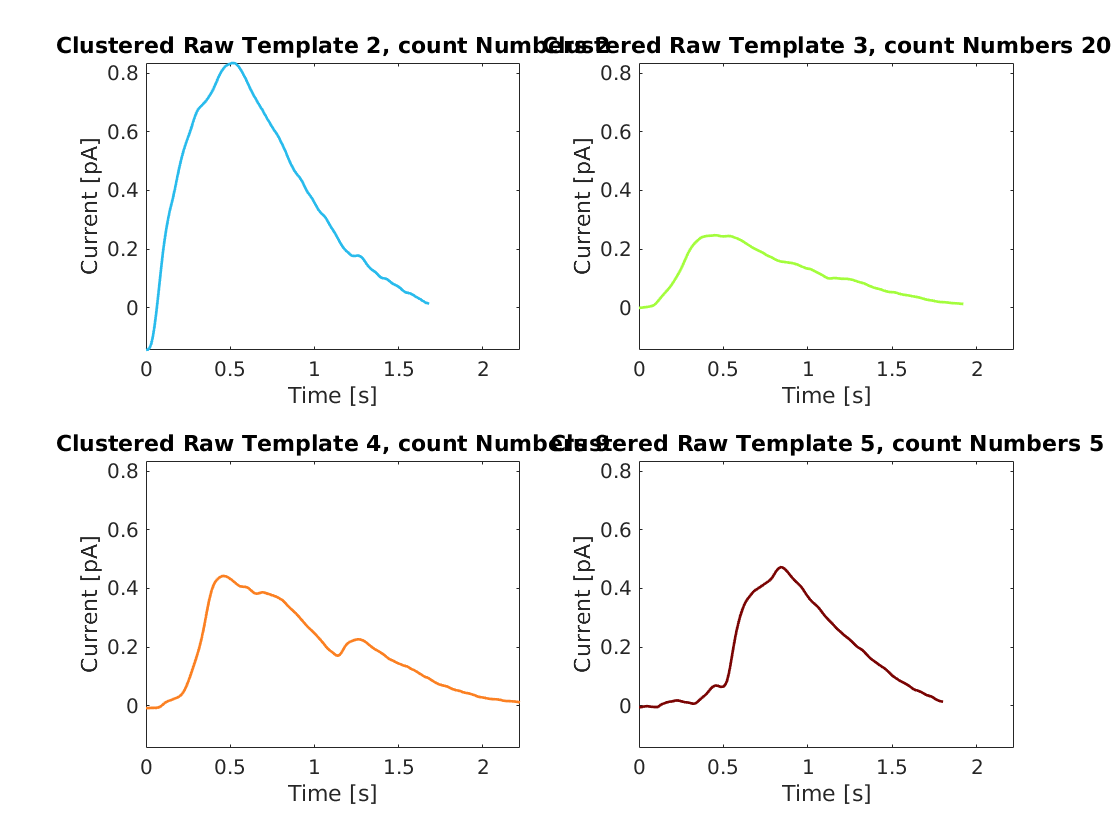

Sig1 = Sig1.RawtemplatesReguFunc([2,3,4,5],'Y');

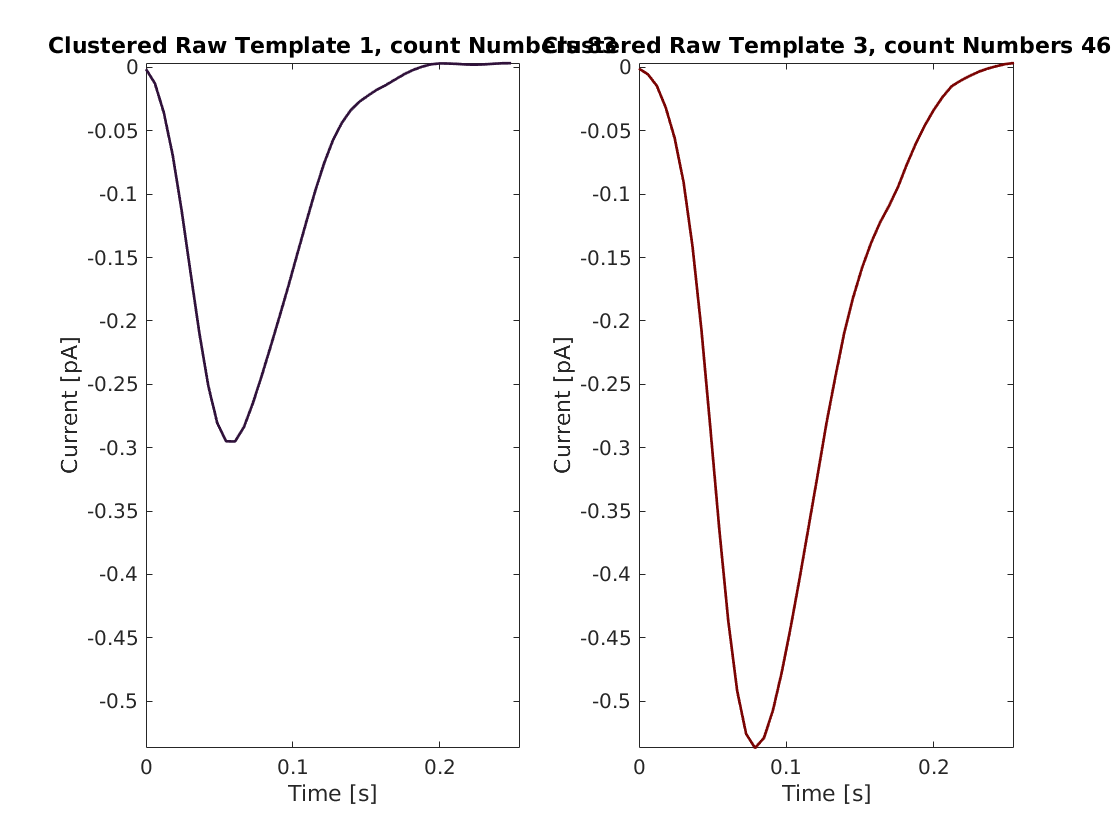

Sig2 = Sig2.RawtemplatesReguFunc([1,3],'Y');

## Template Matching

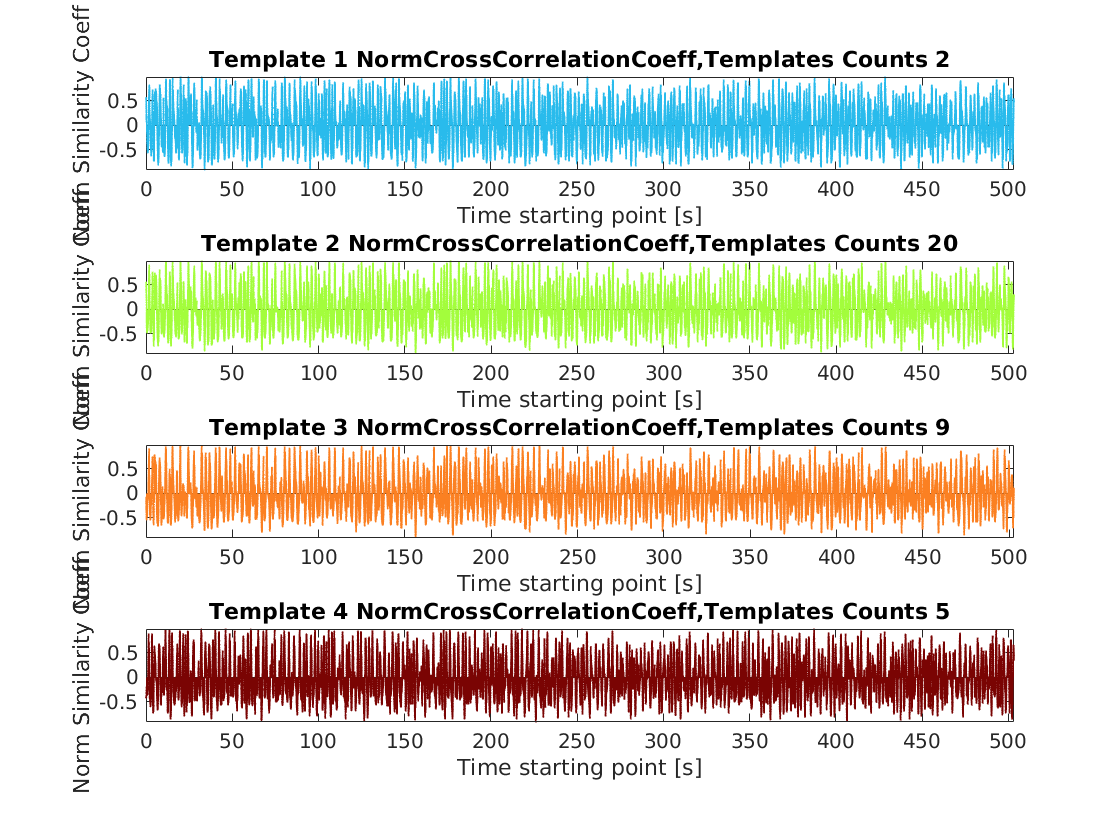

Sig1 = Sig1.Templatematching('Y');

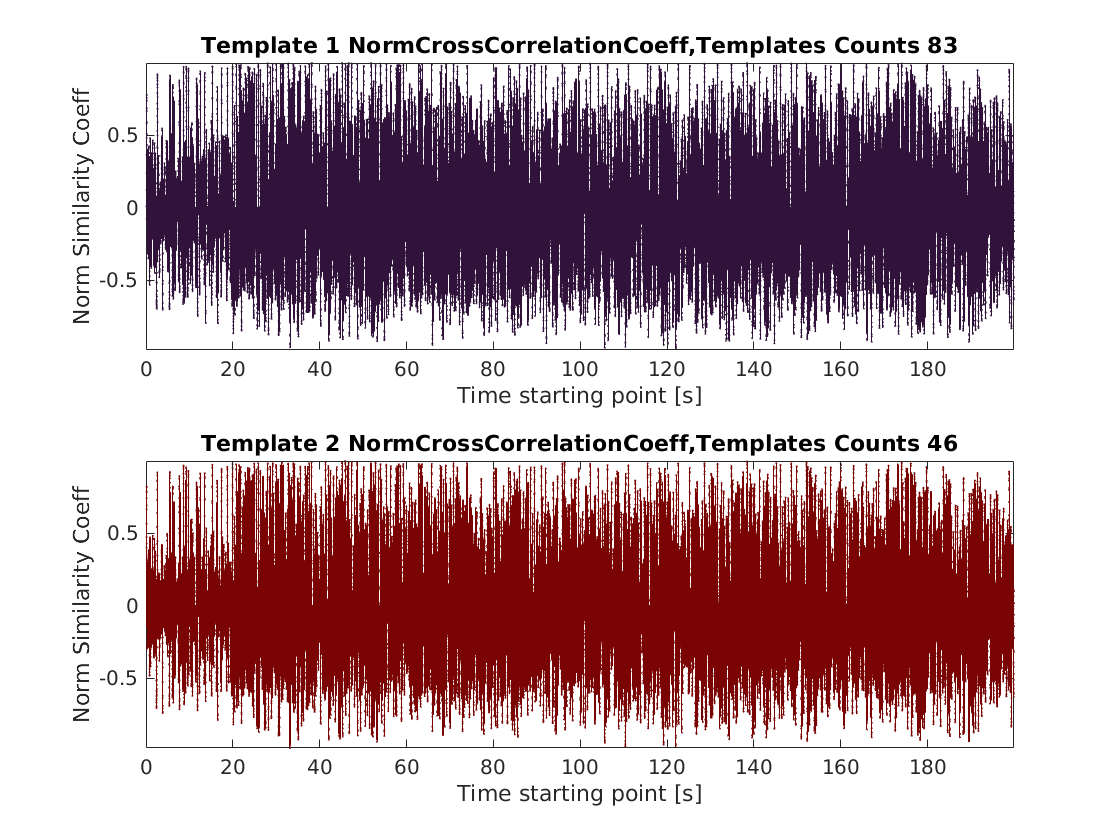

Sig2 = Sig2.Templatematching('Y');

## Template filtered the peaks Sig1

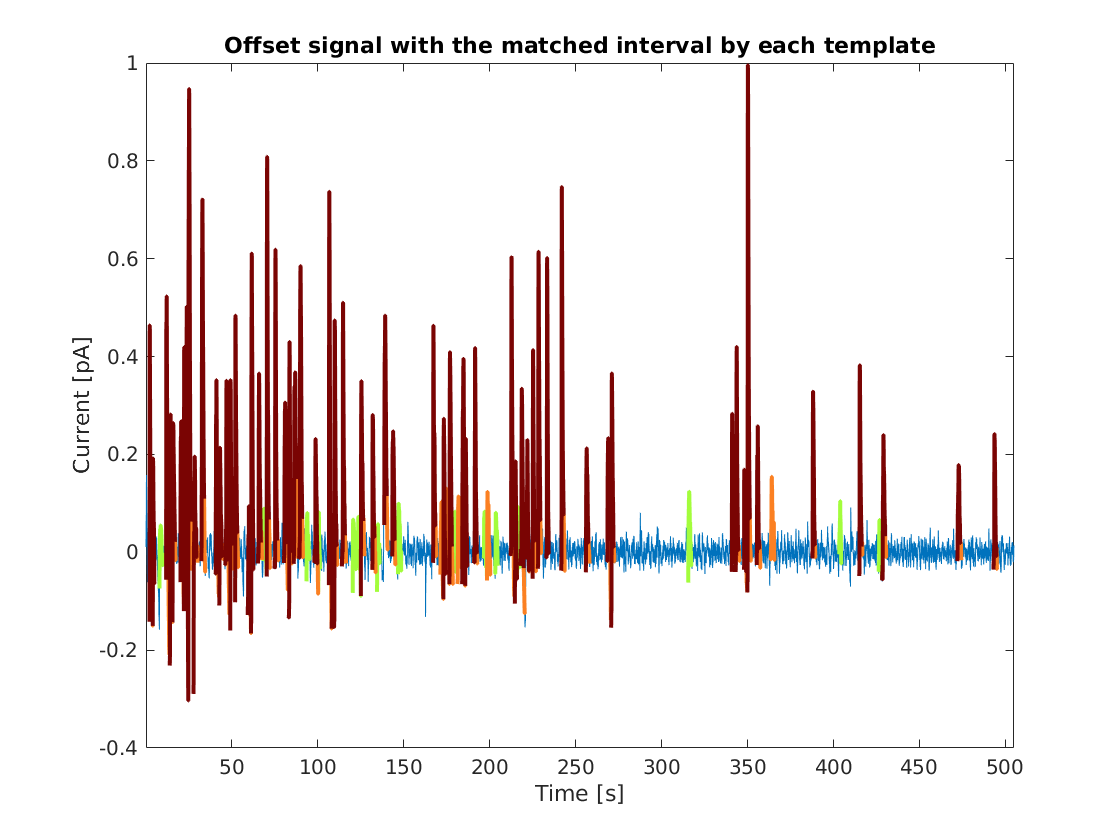

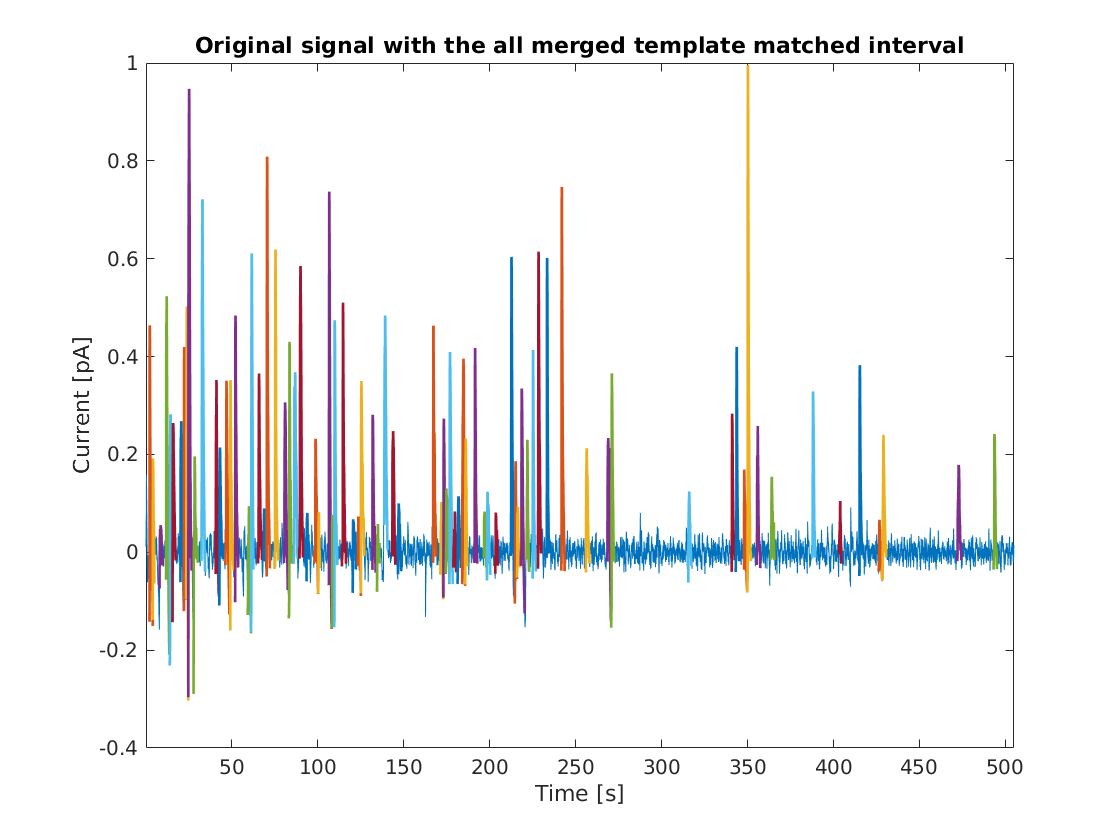

Sim = 0.9;
StdCoeff = 0.35;
HeightWidth = 0.35;
Sig1 = Sig1.TemplatematchingFiltering(Sim,StdCoeff,HeightWidth,'Y','Y');

## Template filtered the peaks Sig2

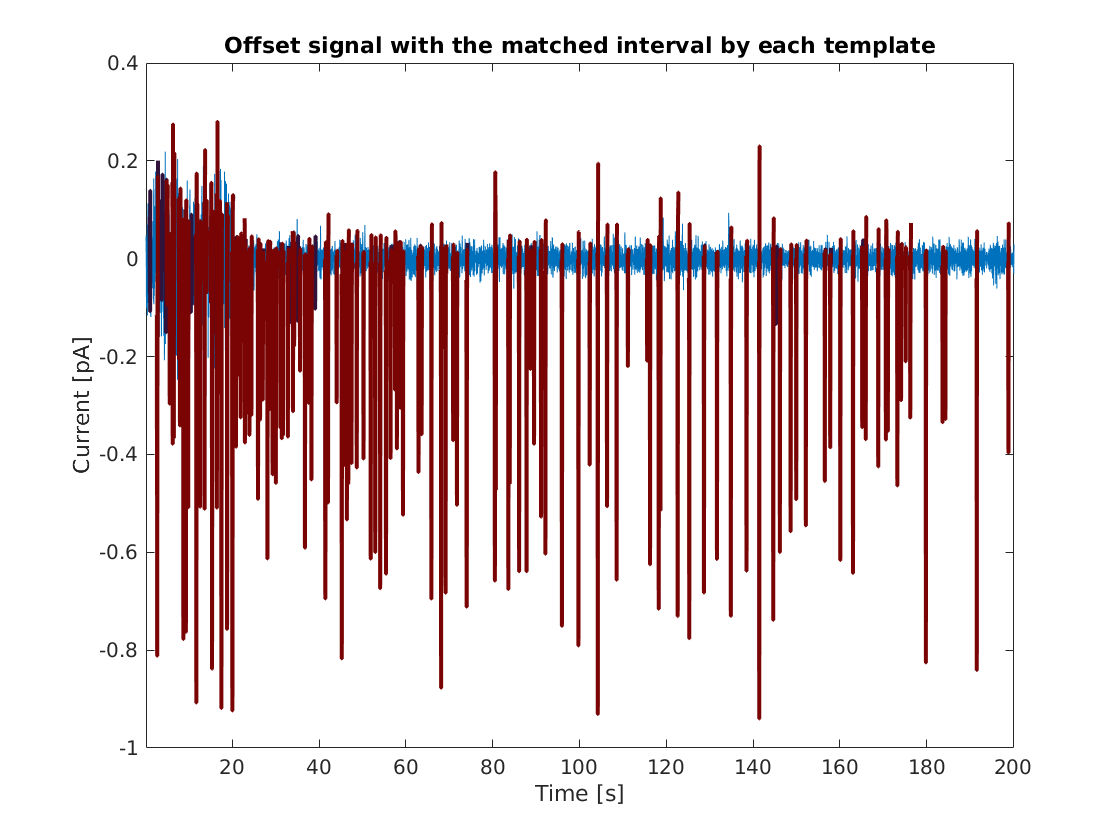

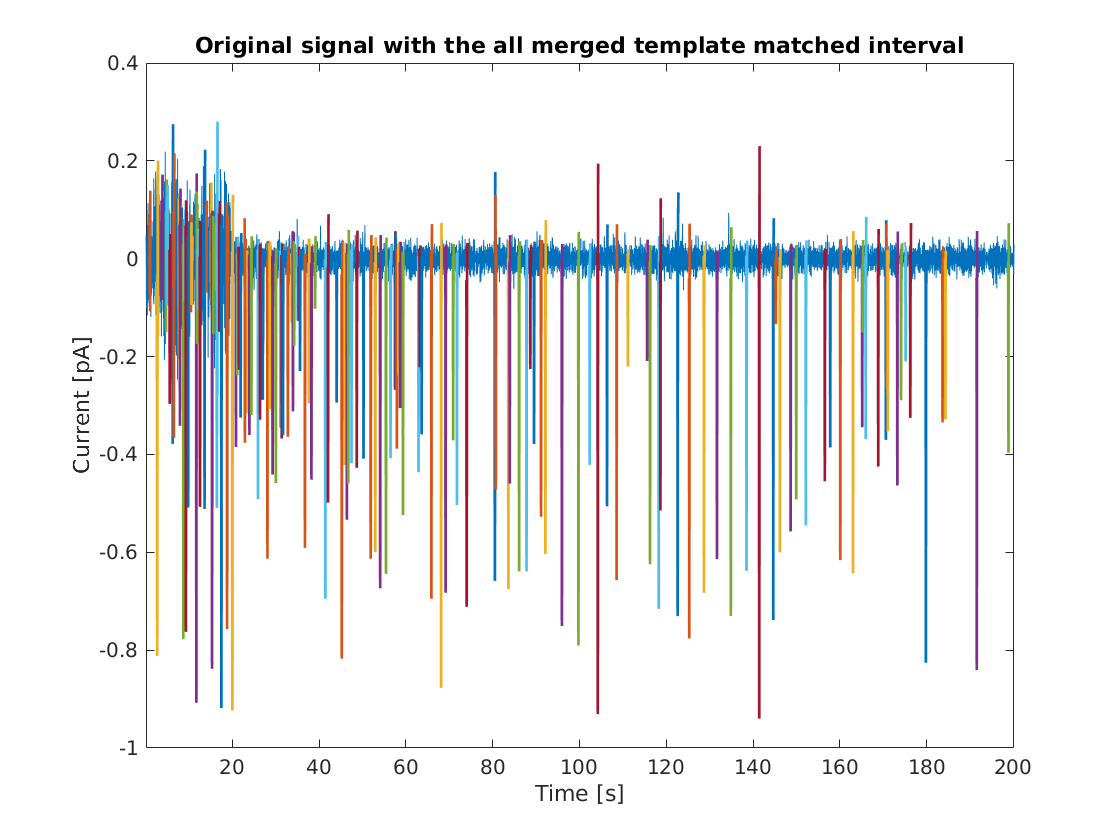

Sim = 0.9;
StdCoeff = 0.35;
HeightWidth = 0.35;
Sig2 = Sig2.TemplatematchingFiltering(Sim,StdCoeff,HeightWidth,'Y','Y');

## TraninignSet ReClustering

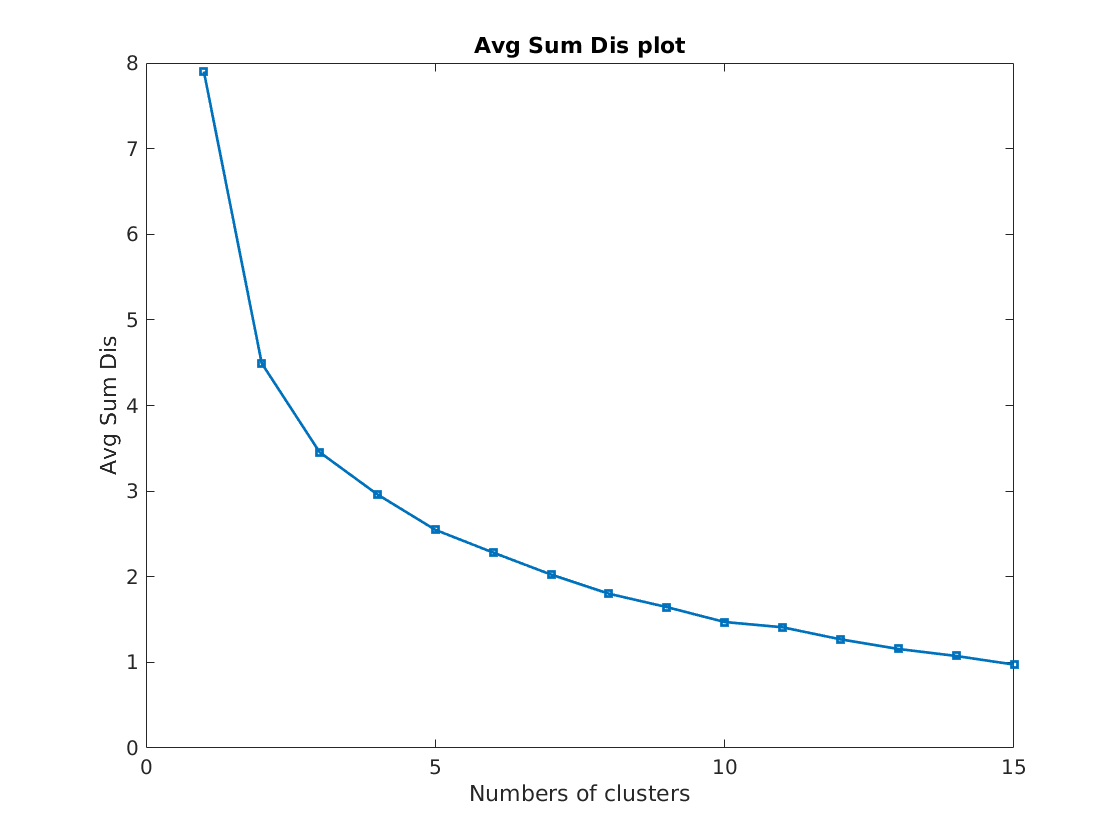

Sig1 = Sig1.GeAMTrainSet('N','Y',"N");

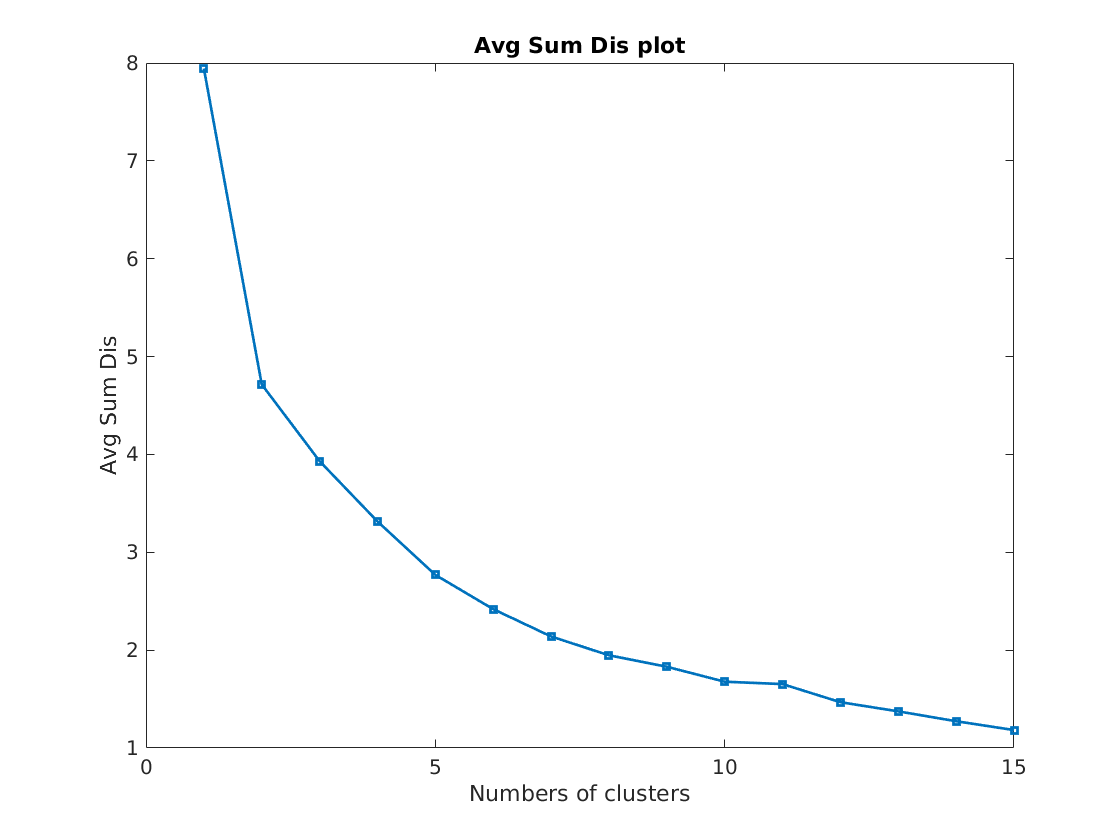

Sig2 = Sig2.GeAMTrainSet('Y','Y',"N");

## ReClustering and generate the templates

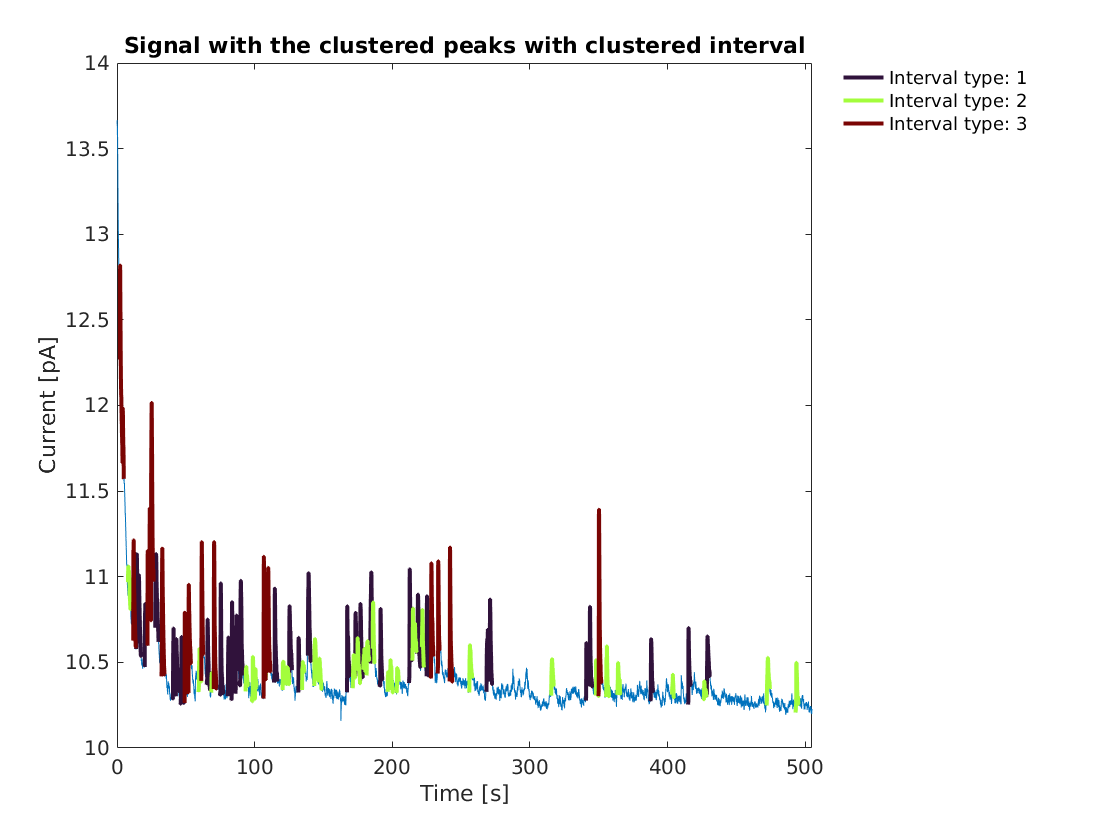

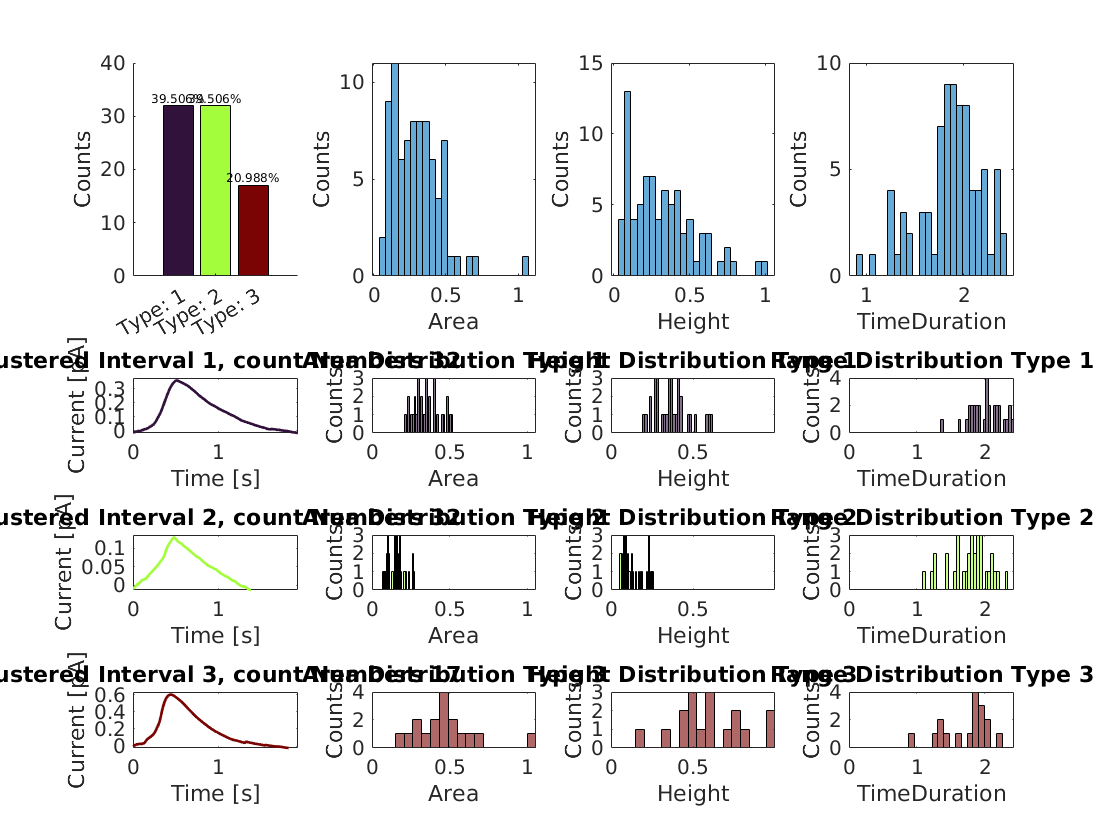

Sig1 = Sig1.KmeansGeAMSigTem(3,"Y","Y");

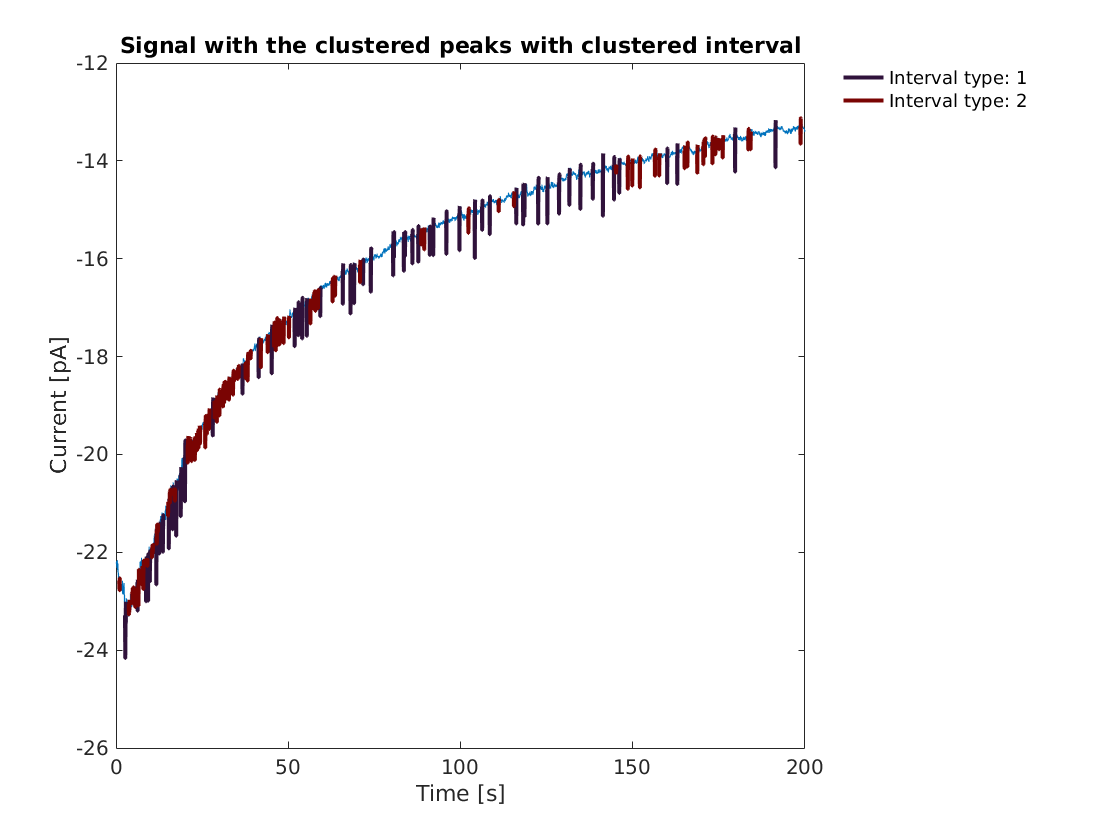

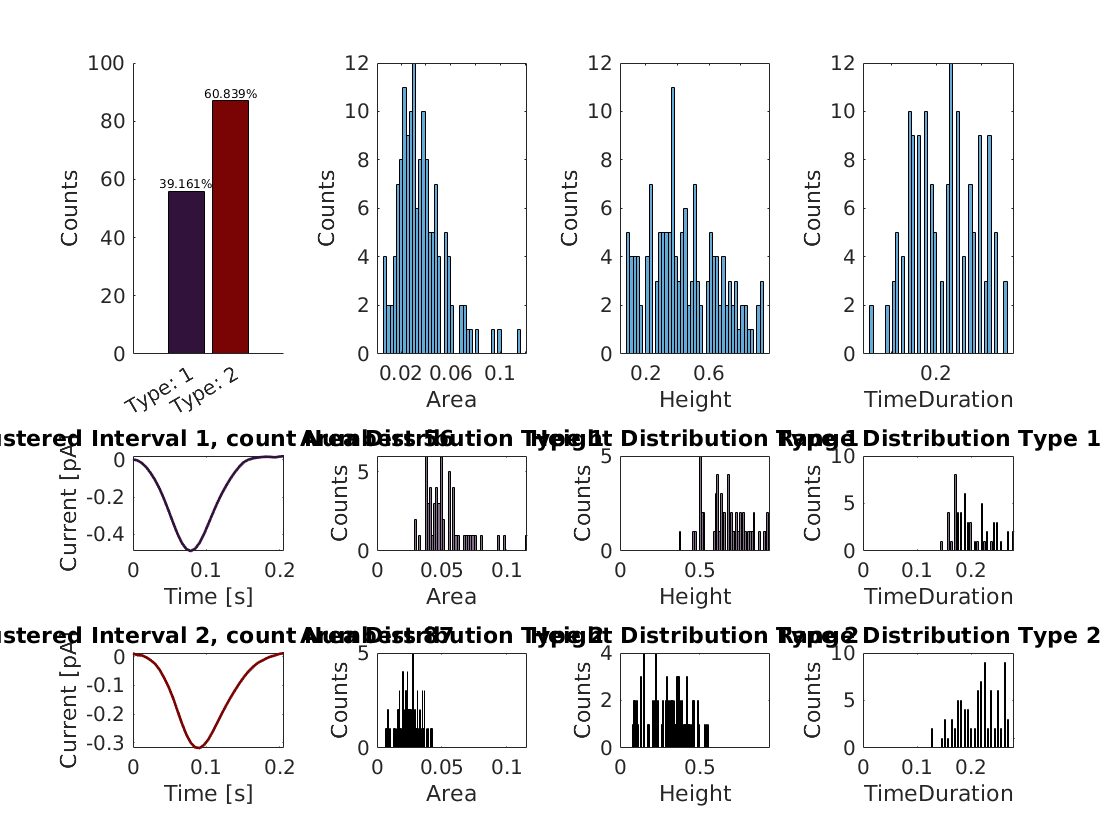

Sig2 = Sig2.KmeansGeAMSigTem(2,"Y","Y");

## Rematching Effect

it will replace the regulated raw templates by the new templates Sig1 = Sig1.Rematching(6,"Y","Y");

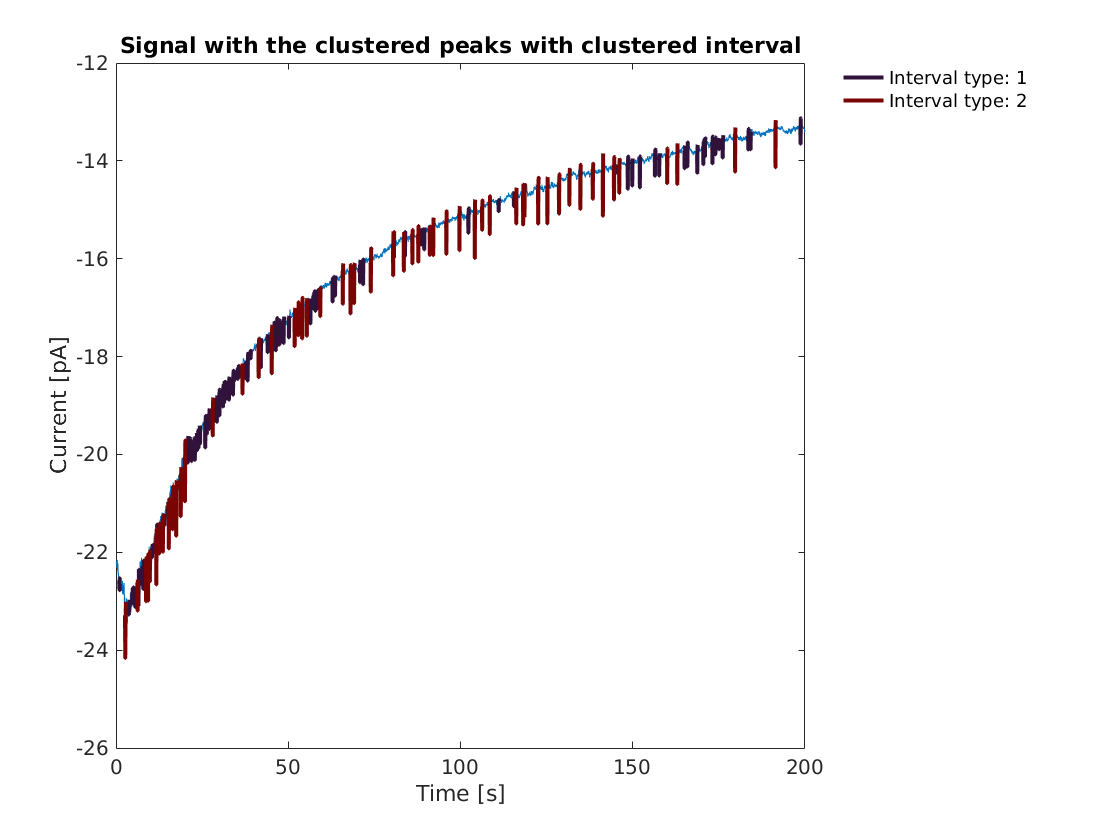

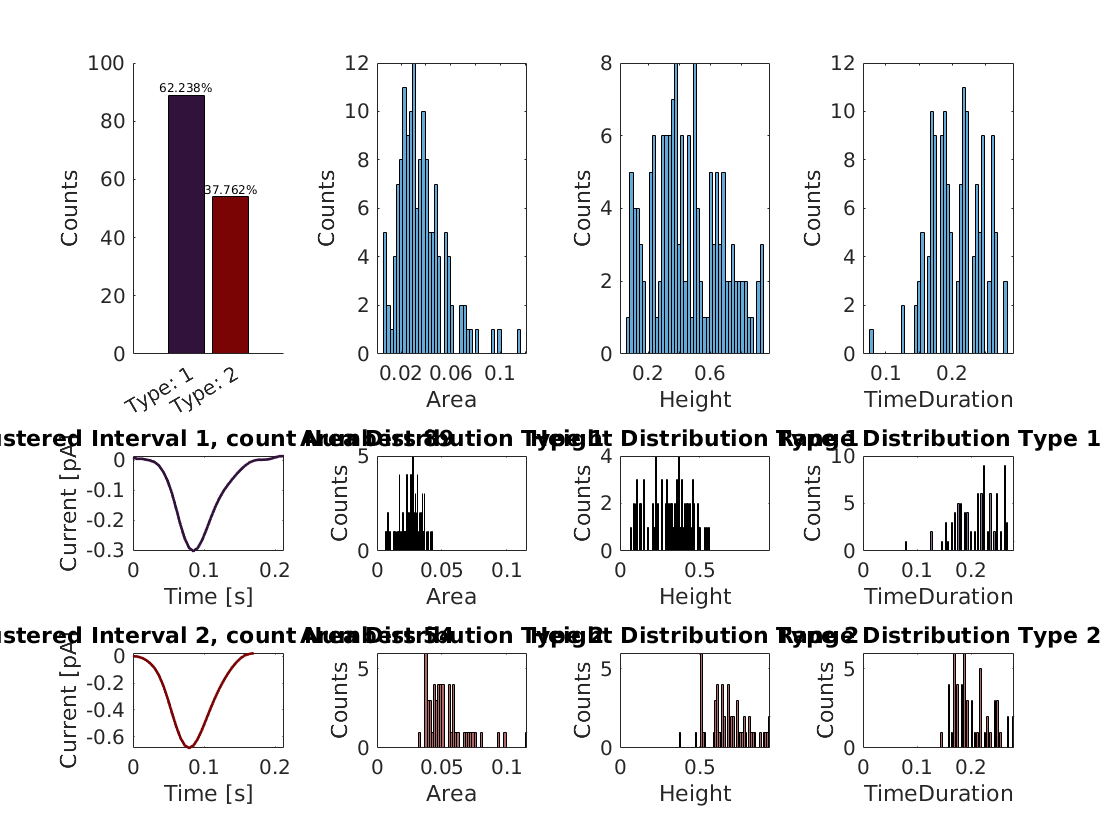

Sig3 = Sig2.KmeansGeAMSigTem(2,"N","N");
Sig3 = Sig3.Rematching(5,"Y","Y");